x=16;
y=4;
b=2;
d=2;
f=3;
h=2;

B=[x/2;y+b;0];
D=[x+d;y/2;0];
F=[x/2;-f;0];
H=[-h;y/2;0];

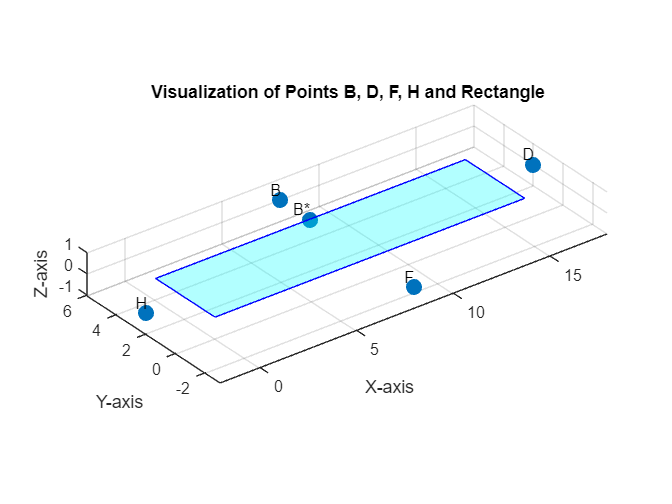

Bstar=[x/2;y;0];
% Combine points into a matrix for plotting
pnts = [B, D, F, H, Bstar];

Bpnts=[B,Bstar];

% Create a rigid transformation (example: rotation + translation)
%theta = pi/4; % Rotation angle (45 degrees)
% theta=0;
% tform = rigidtform3d( ...
%     [cos(theta), -sin(theta), 0, 0; ... % Rotation matrix + translation
%      sin(theta),  cos(theta), 0, 0; ...
%      0,           0,          1, 1]);  % Translation along Z

R_F = [-1  0  0;
        0 -1  0;
         0  0  1];
%t_F = [0, b + f, 0];
%t_F = [0, 0, 0];
t_F = [x, f, 0];


% R_F = [1  0  0;
%         0 1  0;
%         0  0  1];
% t_F = [0, -(b+f+y), 0];

T_F = rigidtform3d(R_F, t_F);

% Apply the rigid transformation to Bpnts
BpntsTransformed = transformPointsForward(T_F, Bpnts');

% Define the rectangle corners
rectX = [0, 0, x, x];
rectY = [0, y, y, 0];
rectZ = [0, 0, 0, 0]; % Rectangle lies in the XY plane (Z = 0)
% Plot the points
figure;
scatter3(pnts(1,:), pnts(2,:), pnts(3,:), 100, 'filled');
text(pnts(1,:), pnts(2,:), pnts(3,:), {'B', 'D', 'F', 'H','B*'}, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');

% Plot the rectangle
hold on;
fill3(rectX, rectY, rectZ, 'cyan', 'FaceAlpha', 0.3, 'EdgeColor', 'blue');

% Formatting the plot
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');
grid on;
title('Visualization of Points B, D, F, H and Rectangle');
axis equal;
hold off;

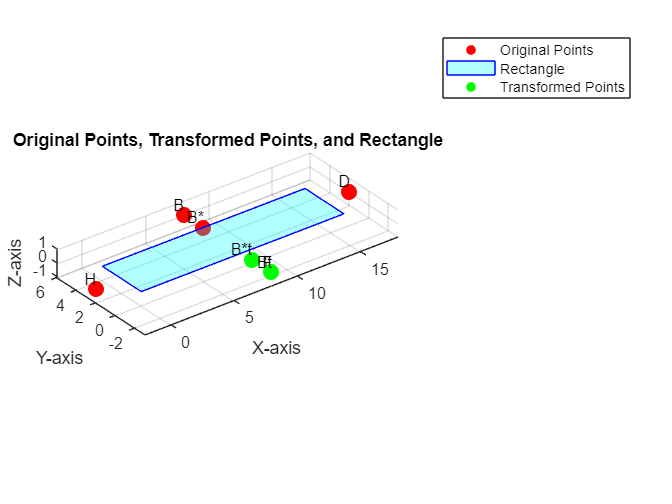

% Create the plot
figure;

% Plot the original points
scatter3(pnts(1,:), pnts(2,:), pnts(3,:), 100, 'filled', 'r'); % Original points
text(pnts(1,:), pnts(2,:), pnts(3,:), {'B', 'D', 'F', 'H', 'B*'}, ...
    'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
hold on;

% Plot the rectangle
fill3(rectX, rectY, rectZ, 'cyan', 'FaceAlpha', 0.3, 'EdgeColor', 'blue');

% Plot the transformed points
scatter3(BpntsTransformed(:,1), BpntsTransformed(:,2), BpntsTransformed(:,3), ...
    100, 'filled', 'g'); % Transformed points

% Label the transformed points
labels = {'Bt', 'B*t'};
for i = 1:length(labels)
    text(BpntsTransformed(i,1), BpntsTransformed(i,2), BpntsTransformed(i,3), ...
        labels{i}, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end

% Formatting the plot
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');
grid on;
title('Original Points, Transformed Points, and Rectangle');
legend('Original Points', 'Rectangle', 'Transformed Points');
axis equal;
hold off;

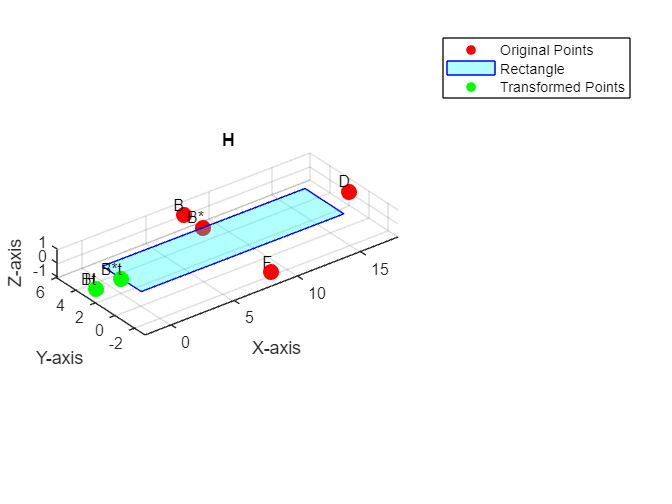

%     [cos(theta), -sin(theta), 0, 0; ... % Rotation matrix + translation
%      sin(theta),  cos(theta), 0, 0; .
theta=pi/2;
R_F = [cos(theta),-sin(theta),  0;
        sin(theta),cos(theta),  0;
        0,0,1;];
%t_F = [0, b + f, 0];
%t_F = [0, 0, 0];
t_F = [y+b-h, -x/2+y/2, 0];


% R_F = [1  0  0;
%         0 1  0;
%         0  0  1];
% t_F = [0, -(b+f+y), 0];

T_F = rigidtform3d(R_F, t_F);

% Apply the rigid transformation to Bpnts
BpntsTransformed = transformPointsForward(T_F, Bpnts');
% Create the plot
figure;

% Plot the original points
scatter3(pnts(1,:), pnts(2,:), pnts(3,:), 100, 'filled', 'r'); % Original points
text(pnts(1,:), pnts(2,:), pnts(3,:), {'B', 'D', 'F', 'H', 'B*'}, ...
    'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
hold on;

% Plot the rectangle
fill3(rectX, rectY, rectZ, 'cyan', 'FaceAlpha', 0.3, 'EdgeColor', 'blue');

% Plot the transformed points
scatter3(BpntsTransformed(:,1), BpntsTransformed(:,2), BpntsTransformed(:,3), ...
    100, 'filled', 'g'); % Transformed points

% Label the transformed points
labels = {'Bt', 'B*t'};
for i = 1:length(labels)
    text(BpntsTransformed(i,1), BpntsTransformed(i,2), BpntsTransformed(i,3), ...
        labels{i}, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end

% Formatting the plot
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');
grid on;
title('H');
legend('Original Points', 'Rectangle', 'Transformed Points');
axis equal;
hold off;

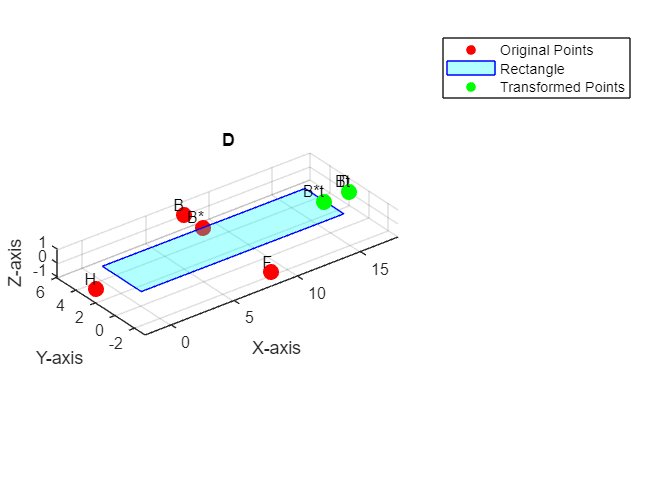

%     [cos(theta), -sin(theta), 0, 0; ... % Rotation matrix + translation
%      sin(theta),  cos(theta), 0, 0; .
theta=-(pi/2);
R_F = [cos(theta),-sin(theta),  0;
        sin(theta),cos(theta),  0;
        0,0,1;];
%t_F = [0, b + f, 0];
%t_F = [0, 0, 0];
t_F = [-(y+b)+x+d, (x/2)+y/2, 0];


% R_F = [1  0  0;
%         0 1  0;
%         0  0  1];
% t_F = [0, -(b+f+y), 0];

T_F = rigidtform3d(R_F, t_F);

% Apply the rigid transformation to Bpnts
BpntsTransformed = transformPointsForward(T_F, Bpnts');
% Create the plot
figure;

% Plot the original points
scatter3(pnts(1,:), pnts(2,:), pnts(3,:), 100, 'filled', 'r'); % Original points
text(pnts(1,:), pnts(2,:), pnts(3,:), {'B', 'D', 'F', 'H', 'B*'}, ...
    'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
hold on;

% Plot the rectangle
fill3(rectX, rectY, rectZ, 'cyan', 'FaceAlpha', 0.3, 'EdgeColor', 'blue');

% Plot the transformed points
scatter3(BpntsTransformed(:,1), BpntsTransformed(:,2), BpntsTransformed(:,3), ...
    100, 'filled', 'g'); % Transformed points

% Label the transformed points
labels = {'Bt', 'B*t'};
for i = 1:length(labels)
    text(BpntsTransformed(i,1), BpntsTransformed(i,2), BpntsTransformed(i,3), ...
        labels{i}, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end

% Formatting the plot
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');
grid on;
title('D');
legend('Original Points', 'Rectangle', 'Transformed Points');
axis equal;
hold off;

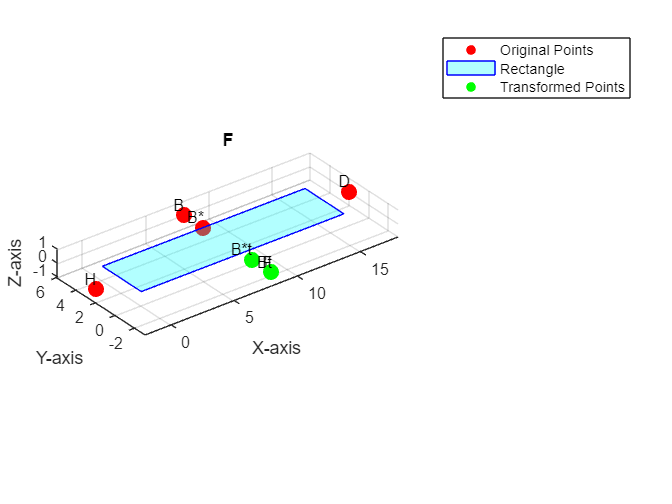

%     [cos(theta), -sin(theta), 0, 0; ... % Rotation matrix + translation
%      sin(theta),  cos(theta), 0, 0; .
theta=pi;
R_F = [cos(theta),-sin(theta),  0;
        sin(theta),cos(theta),  0;
        0,0,1;];
%t_F = [0, b + f, 0];
%t_F = [0, 0, 0];
t_F = [x, y+b-f, 0];


% R_F = [1  0  0;
%         0 1  0;
%         0  0  1];
% t_F = [0, -(b+f+y), 0];

T_F = rigidtform3d(R_F, t_F);

% Apply the rigid transformation to Bpnts
BpntsTransformed = transformPointsForward(T_F, Bpnts');
% Create the plot
figure;

% Plot the original points
scatter3(pnts(1,:), pnts(2,:), pnts(3,:), 100, 'filled', 'r'); % Original points
text(pnts(1,:), pnts(2,:), pnts(3,:), {'B', 'D', 'F', 'H', 'B*'}, ...
    'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
hold on;

% Plot the rectangle
fill3(rectX, rectY, rectZ, 'cyan', 'FaceAlpha', 0.3, 'EdgeColor', 'blue');

% Plot the transformed points
scatter3(BpntsTransformed(:,1), BpntsTransformed(:,2), BpntsTransformed(:,3), ...
    100, 'filled', 'g'); % Transformed points

% Label the transformed points
labels = {'Bt', 'B*t'};
for i = 1:length(labels)
    text(BpntsTransformed(i,1), BpntsTransformed(i,2), BpntsTransformed(i,3), ...
        labels{i}, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end

% Formatting the plot
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');
grid on;
title('F');
legend('Original Points', 'Rectangle', 'Transformed Points');
axis equal;
hold off;

%Summary

B to F

theta=pi;
R_B_to_F = [cos(theta),-sin(theta),  0;
        sin(theta),cos(theta),  0;
        0,0,1;];
t_B_to_F = [x, y+b-f, 0];

B to D

theta=-(pi/2);
R_B_to_D = [cos(theta),-sin(theta),  0;
        sin(theta),cos(theta),  0;
        0,0,1;];
t_B_to_D = [-(y+b)+x+d, (x/2)+y/2, 0];

B to H

theta=pi/2;
R_B_to_H = [cos(theta),-sin(theta),  0;
        sin(theta),cos(theta),  0;
        0,0,1;];
t_B_to_H = [y+b-h, -x/2+y/2, 0];

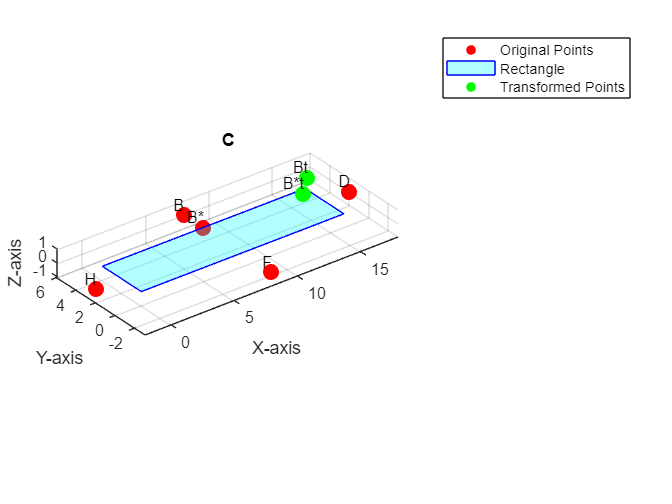

%     [cos(theta), -sin(theta), 0, 0; ... % Rotation matrix + translation
%      sin(theta),  cos(theta), 0, 0; .
c=sqrt(2);
theta=-pi/4;
%theta=-(5*pi/12)
R_F = [cos(theta),-sin(theta),  0;
        sin(theta),cos(theta),  0;
        0,0,1;];
%t_F = [0, b + f, 0];
%t_F = [0, 0, 0];
%t_F = [x, y+b-f, 0];

% t_F= [(cosd(-45)*(x/2 + y + b)+sind(-45)*(y + b))+y+(sind(-45)*c); 
%                         (-sind(-45)*(x/2 + y + b)+cosd(-45)*(y + b))+x+(cosd(-45)*c);0];

t_F = [(-1*(sqrt(2)/2)*(x/2 + y + b))+x+sind(45)*c;
       (1*(sqrt(2)/2)*(-(y + b) + (x/2)))+y+sind(45)*c;
       0];
% R_F = [1  0  0;
%         0 1  0;
%         0  0  1];
% t_F = [0, -(b+f+y), 0];

T_F = rigidtform3d(R_F, t_F);

% Apply the rigid transformation to Bpnts
BpntsTransformed = transformPointsForward(T_F, Bpnts');
% Create the plot
figure;

% Plot the original points
scatter3(pnts(1,:), pnts(2,:), pnts(3,:), 100, 'filled', 'r'); % Original points
text(pnts(1,:), pnts(2,:), pnts(3,:), {'B', 'D', 'F', 'H', 'B*'}, ...
    'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
hold on;

% Plot the rectangle
fill3(rectX, rectY, rectZ, 'cyan', 'FaceAlpha', 0.3, 'EdgeColor', 'blue');

% Plot the transformed points
scatter3(BpntsTransformed(:,1), BpntsTransformed(:,2), BpntsTransformed(:,3), ...
    100, 'filled', 'g'); % Transformed points

% Label the transformed points
labels = {'Bt', 'B*t'};
for i = 1:length(labels)
    text(BpntsTransformed(i,1), BpntsTransformed(i,2), BpntsTransformed(i,3), ...
        labels{i}, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end

% Formatting the plot
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');
grid on;
title('C');
legend('Original Points', 'Rectangle', 'Transformed Points');
axis equal;
hold off;

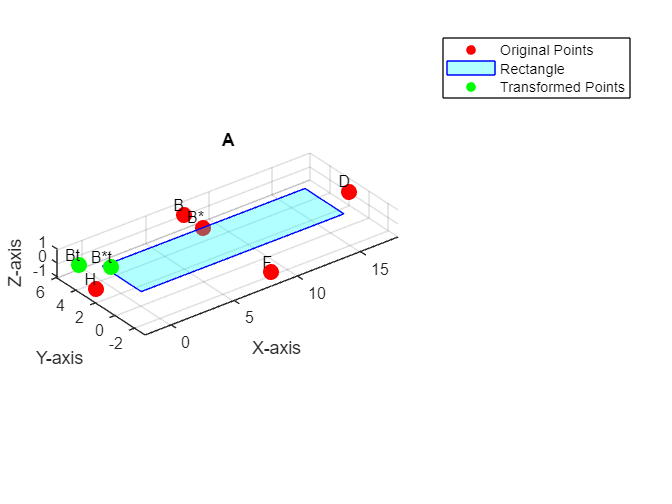

c=sqrt(2);
a=sqrt(2);
theta=pi/4;
%theta=-(5*pi/12)
R_F = [cos(theta),-sin(theta),  0;
        sin(theta),cos(theta),  0;
        0,0,1;];
%t_F = [0, b + f, 0];
%t_F = [0, 0, 0];
%t_F = [x, y+b-f, 0];

% t_F= [(cosd(-45)*(x/2 + y + b)+sind(-45)*(y + b))+y+(sind(-45)*c); 
%                         (-sind(-45)*(x/2 + y + b)+cosd(-45)*(y + b))+x+(cosd(-45)*c);0];

%t_F = [(-1*(sqrt(2)/2)*(x/2 + y + b));
     %  (1*(sqrt(2)/2)*(-(y + b) + (x/2)));
      % 0];
% R_F = [1  0  0;
%         0 1  0;
%         0  0  1];
% t_F = [0, -(b+f+y), 0];


t_F = [(-1*(sqrt(2)/2)*(-(y + b) + (x/2)))-sind(45)*a;
      (-1*(sqrt(2)/2)*(x/2 + y + b))+y+sind(45)*a;
      0];
T_F = rigidtform3d(R_F, t_F);

% Apply the rigid transformation to Bpnts
BpntsTransformed = transformPointsForward(T_F, Bpnts');
% Create the plot
figure;

% Plot the original points
scatter3(pnts(1,:), pnts(2,:), pnts(3,:), 100, 'filled', 'r'); % Original points
text(pnts(1,:), pnts(2,:), pnts(3,:), {'B', 'D', 'F', 'H', 'B*'}, ...
    'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
hold on;

% Plot the rectangle
fill3(rectX, rectY, rectZ, 'cyan', 'FaceAlpha', 0.3, 'EdgeColor', 'blue');

% Plot the transformed points
scatter3(BpntsTransformed(:,1), BpntsTransformed(:,2), BpntsTransformed(:,3), ...
    100, 'filled', 'g'); % Transformed points

% Label the transformed points
labels = {'Bt', 'B*t'};
for i = 1:length(labels)
    text(BpntsTransformed(i,1), BpntsTransformed(i,2), BpntsTransformed(i,3), ...
        labels{i}, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end

% Formatting the plot
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');
grid on;
title('A');
legend('Original Points', 'Rectangle', 'Transformed Points');
axis equal;
hold off;

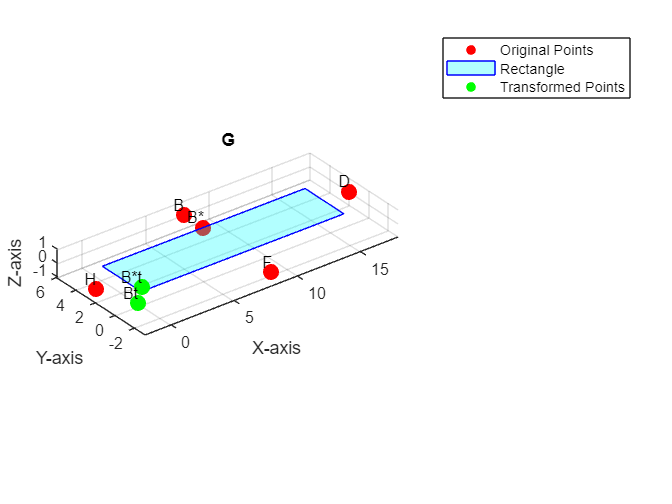

c=sqrt(2);
a=sqrt(2);
g=sqrt(2);
theta=pi/2 + pi/4;
%theta=-(5*pi/12)
R_F = [cos(theta),-sin(theta),  0;
        sin(theta),cos(theta),  0;
        0,0,1;];
%t_F = [0, b + f, 0];
%t_F = [0, 0, 0];
%t_F = [x, y+b-f, 0];

% t_F= [(cosd(-45)*(x/2 + y + b)+sind(-45)*(y + b))+y+(sind(-45)*c); 
%                         (-sind(-45)*(x/2 + y + b)+cosd(-45)*(y + b))+x+(cosd(-45)*c);0];

%t_F = [(-1*(sqrt(2)/2)*(x/2 + y + b));
     %  (1*(sqrt(2)/2)*(-(y + b) + (x/2)));
      % 0];
% R_F = [1  0  0;
%         0 1  0;
%         0  0  1];
% t_F = [0, -(b+f+y), 0];


t_F = [1*(sqrt(2)/2)*(x/2 + y + b)-g*sind(45);
     -1*((sqrt(2)/2)*(-(y + b) + (x/2)))-g*sind(45);
      0];
T_F = rigidtform3d(R_F, t_F);

% Apply the rigid transformation to Bpnts
BpntsTransformed = transformPointsForward(T_F, Bpnts');
% Create the plot
figure;

% Plot the original points
scatter3(pnts(1,:), pnts(2,:), pnts(3,:), 100, 'filled', 'r'); % Original points
text(pnts(1,:), pnts(2,:), pnts(3,:), {'B', 'D', 'F', 'H', 'B*'}, ...
    'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
hold on;

% Plot the rectangle
fill3(rectX, rectY, rectZ, 'cyan', 'FaceAlpha', 0.3, 'EdgeColor', 'blue');

% Plot the transformed points
scatter3(BpntsTransformed(:,1), BpntsTransformed(:,2), BpntsTransformed(:,3), ...
    100, 'filled', 'g'); % Transformed points

% Label the transformed points
labels = {'Bt', 'B*t'};
for i = 1:length(labels)
    text(BpntsTransformed(i,1), BpntsTransformed(i,2), BpntsTransformed(i,3), ...
        labels{i}, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end

% Formatting the plot
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');
grid on;
title('G');
legend('Original Points', 'Rectangle', 'Transformed Points');
axis equal;
hold off;

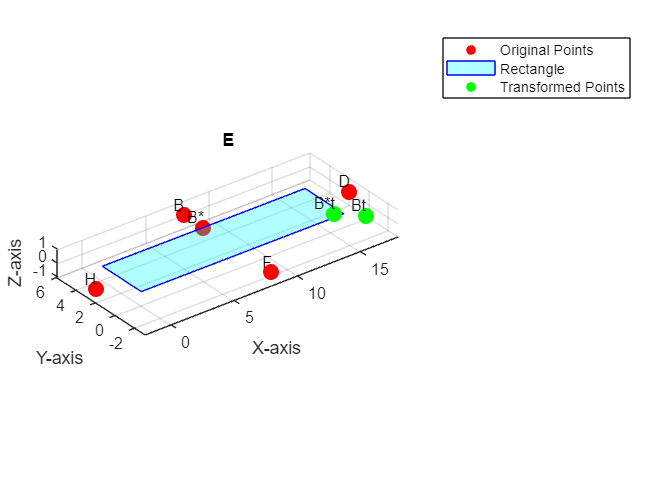

c=sqrt(2);
a=sqrt(2);
g=sqrt(2);
e_small=sqrt(2);
theta=pi + pi/4;
%theta=-(5*pi/12)
R_F = [cos(theta),-sin(theta),  0;
        sin(theta),cos(theta),  0;
        0,0,1;];
%t_F = [0, b + f, 0];
t_F = [0, 0, 0];
%t_F = [x, y+b-f, 0];

% t_F= [(cosd(-45)*(x/2 + y + b)+sind(-45)*(y + b))+y+(sind(-45)*c); 
%                         (-sind(-45)*(x/2 + y + b)+cosd(-45)*(y + b))+x+(cosd(-45)*c);0];

%t_F = [(-1*(sqrt(2)/2)*(x/2 + y + b));
     %  (1*(sqrt(2)/2)*(-(y + b) + (x/2)));
      % 0];
% R_F = [1  0  0;
%         0 1  0;
%         0  0  1];
% t_F = [0, -(b+f+y), 0];


t_F = [(1*((sqrt(2)/2)*(-(y + b) + (x/2))))+x+(e_small*sind(45));
    (1*(sqrt(2)/2)*(x/2 + y + b))-(e_small*sind(45));
    0];
T_F = rigidtform3d(R_F, t_F);

% Apply the rigid transformation to Bpnts
BpntsTransformed = transformPointsForward(T_F, Bpnts');
% Create the plot
figure;

% Plot the original points
scatter3(pnts(1,:), pnts(2,:), pnts(3,:), 100, 'filled', 'r'); % Original points
text(pnts(1,:), pnts(2,:), pnts(3,:), {'B', 'D', 'F', 'H', 'B*'}, ...
    'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
hold on;

% Plot the rectangle
fill3(rectX, rectY, rectZ, 'cyan', 'FaceAlpha', 0.3, 'EdgeColor', 'blue');

% Plot the transformed points
scatter3(BpntsTransformed(:,1), BpntsTransformed(:,2), BpntsTransformed(:,3), ...
    100, 'filled', 'g'); % Transformed points

% Label the transformed points
labels = {'Bt', 'B*t'};
for i = 1:length(labels)
    text(BpntsTransformed(i,1), BpntsTransformed(i,2), BpntsTransformed(i,3), ...
        labels{i}, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end

% Formatting the plot
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');
grid on;
title('E');
legend('Original Points', 'Rectangle', 'Transformed Points');
axis equal;
hold off;

arrTformstest=matrix_align(x,y,a,b,c,d,e_small,f,g,h);